% Initial date & time
startTime = datetime(2020,6,02,8,23,0);
stopTime = startTime + days(1);
sampleTime = 60;
sc = satelliteScenario(startTime,stopTime,sampleTime);
lat = 10;
lon = -30;
gs = groundStation(sc,lat,lon);
jd = juliandate(startTime);

% Generating debris with random Keplerian elements
semiMajorAxis=[];
eccentricity = [];
inclination = [];
rightAscensionOfAscendingNode = [];
argumentOfPeriapsis = [];
trueAnomaly = [];
sat=[];
Y = double(sat);
for n = 1:1 % Generated for single debris
    i1 = randi([6527347,8377162],1);
        semiMajorAxis(n) = i1*(1+rand())
        eccentricity(n) = rand()
        if semiMajorAxis(n)>=8377999.7162 || semiMajorAxis(n)<=13054041.2653
           eccentricity(n) = rand()/100
        end
        inclination(n) = randi([0,179],1)
        rightAscensionOfAscendingNode(n) = randi(360,1)
        argumentOfPeriapsis(n) = randi(360,1)
        trueAnomaly(n) = randi(360,1)

        N = string(n);
        Y = satellite(sc,semiMajorAxis,eccentricity,inclination, ...
        rightAscensionOfAscendingNode,argumentOfPeriapsis,trueAnomaly,Name=N)
end

semiMajorAxis = 7.9943e+06

eccentricity = 0.6054

eccentricity = 0.0058

inclination = 145

rightAscensionOfAscendingNode = 236

argumentOfPeriapsis = 317

trueAnomaly = 325

Y =   Satellite with properties:

                  Name:  1
                    ID:  2
        ConicalSensors:  [1x0 matlabshared.satellitescenario.ConicalSensor]
               Gimbals:  [1x0 matlabshared.satellitescenario.Gimbal]
          Transmitters:  [1x0 satcom.satellitescenario.Transmitter]
             Receivers:  [1x0 satcom.satellitescenario.Receiver]
              Accesses:  [1x0 matlabshared.satellitescenario.Access]
               Eclipse:  [1x0 Aero.satellitescenario.Eclipse]
           GroundTrack:  [1x1 matlabshared.satellitescenario.GroundTrack]
                 Orbit:  [1x1 matlabshared.satellitescenario.Orbit]
        CoordinateAxes:  [1x1 matlabshared.satellitescenario.CoordinateAxes]
       OrbitPropagator:  sgp4
           MarkerColor:  [0.059 1 1]
            MarkerSize:  6
             ShowLabel:  true
        LabelFontColor:  [1 1 1]
         LabelFontSize:  15
         Visual3DModel:  
    

[deb_pos,deb_velocity,deb_timeOut] = states(Y,"CoordinateFrame",'inertial')

deb_pos = 1.0e+06 *

    4.3637    4.0641    3.7529    3.4310    3.0993    2.7588    2.4105    2.0552    1.6941    1.3282    0.9585    0.5860    0.2119   -0.1629   -0.5371   -0.9099   -1.2800   -1.6465   -2.0083   -2.3643   -2.7136   -3.0552   -3.3880   -3.7112   -4.0238   -4.3249   -4.6137   -4.8894   -5.1511   -5.3983   -5.6300   -5.8458   -6.0450   -6.2271   -6.3915   -6.5378   -6.6656   -6.7746   -6.8645   -6.9350   -6.9860   -7.0173   -7.0288   -7.0206   -6.9927   -6.9452   -6.8782   -6.7920   -6.6867   -6.5628
   -4.9371   -5.2337   -5.5153   -5.7813   -6.0309   -6.2632   -6.4777   -6.6737   -6.8506   -7.0080   -7.1455   -7.2625   -7.3587   -7.4340   -7.4880   -7.5206   -7.5317   -7.5213   -7.4895   -7.4362   -7.3617   -7.2662   -7.1500   -7.0134   -6.8568   -6.6806   -6.4854   -6.2718   -6.0403   -5.7916   -5.5265   -5.2457   -4.9499   -4.6402   -4.3173   -3.9822   -3.6358   -3.2792   -2.9133   -2.5392   -2.1579   -1.7705   -1.3782   -0.9820   -0.5830   -0.1824    0.2187    0.61

deb_velocity = 1.0e+03 *

   -4.8929   -5.0928   -5.2783   -5.4488   -5.6040   -5.7432   -5.8661   -5.9723   -6.0615   -6.1334   -6.1878   -6.2246   -6.2436   -6.2448   -6.2281   -6.1937   -6.1415   -6.0718   -5.9848   -5.8807   -5.7598   -5.6226   -5.4693   -5.3005   -5.1167   -4.9184   -4.7062   -4.4807   -4.2426   -3.9926   -3.7314   -3.4598   -3.1786   -2.8886   -2.5907   -2.2857   -1.9745   -1.6580   -1.3371   -1.0127   -0.6858   -0.3572   -0.0279    0.3011    0.6290    0.9548    1.2776    1.5966    1.9109    2.2195
   -5.0625   -4.8213   -4.5662   -4.2980   -4.0174   -3.7252   -3.4223   -3.1095   -2.7878   -2.4580   -2.1211   -1.7780   -1.4299   -1.0776   -0.7222   -0.3647   -0.0063    0.3522    0.7096    1.0649    1.4171    1.7652    2.1081    2.4448    2.7745    3.0961    3.4086    3.7114    4.0033    4.2837    4.5518    4.8067    5.0478    5.2744    5.4859    5.6817    5.8613    6.0241    6.1698    6.2980    6.4083    6.5005    6.5743    6.6296    6.6662    6.6841    6.6832   

deb_timeOut = 1×1441 datetime array
Columns 1 through 1424

   02-Jun-2020 08:23:00   02-Jun-2020 08:24:00   02-Jun-2020 08:25:00   02-Jun-2020 08:26:00   02-Jun-2020 08:27:00   02-Jun-2020 08:28:00   02-Jun-2020 08:29:00   02-Jun-2020 08:30:00   02-Jun-2020 08:31:00   02-Jun-2020 08:32:00   02-Jun-2020 08:33:00   02-Jun-2020 08:34:00   02-Jun-2020 08:35:00   02-Jun-2020 08:36:00   02-Jun-2020 08:37:00   02-Jun-2020 08:38:00   02-Jun-2020 08:39:00   02-Jun-2020 08:40:00   02-Jun-2020 08:41:00   02-Jun-2020 08:42:00   02-Jun-2020 08:43:00   02-Jun-2020 08:44:00   02-Jun-2020 08:45:00   02-Jun-2020 08:46:00   02-Jun-2020 08:47:00   02-Jun-2020 08:48:00   02-Jun-2020 08:49:00   02-Jun-2020 08:50:00   02-Jun-2020 08:51:00   02-Jun-2020 08:52:00   02-Jun-2020 08:53:00   02-Jun-2020 08:54:00   02-Jun-2020 08:55:00   02-Jun-2020 08:56:00   02-Jun-2020 08:57:00   02-Jun-2020 08:58:00   02-Jun-2020 08:59:00   02-Jun-2020 09:00:00   02-Jun-2020 09:01:00   02-Jun-2020 09:02:00   02-Jun-2020 09:03

% Adding satellites 
constellation=[];
const_semiMajorAxis=[];
const_eccentricity = [];
const_inclination = [];
const_rightAscensionOfAscendingNode = [];
const_argumentOfPeriapsis = [];
const_trueAnomaly = [];

const_Y = double(constellation);
for const_n = 1:1 % Generated for a single satellite
        i = randi([6527347,8377162],1);
        const_semiMajorAxis(const_n) = i*(1+rand())
        const_eccentricity(const_n) = rand()
        if const_semiMajorAxis(const_n)>=8377999.7162 || const_semiMajorAxis(const_n)<=13054041.2653
           const_eccentricity(const_n) = rand()/100
        end
        const_inclination(const_n) = randi([0,179],1)
        const_rightAscensionOfAscendingNode(const_n) = randi(360,1)
        const_argumentOfPeriapsis(const_n) = randi(360,1)
        const_trueAnomaly(const_n) = randi(360,1)

        const_N = string("Constellation satellite "+const_n);
        const_Y = satellite(sc,const_semiMajorAxis,const_eccentricity,const_inclination, ...
        const_rightAscensionOfAscendingNode,const_argumentOfPeriapsis,const_trueAnomaly,Name=const_N)
       
        % const_Y(const_n).MarkerColor = 'red';
end

const_semiMajorAxis = 8.1202e+06

const_eccentricity = 0.7910

const_eccentricity = 6.0705e-04

const_inclination = 70

const_rightAscensionOfAscendingNode = 108

const_argumentOfPeriapsis = 265

const_trueAnomaly = 38

const_Y =   Satellite with properties:

                  Name:  Constellation satellite 1
                    ID:  3
        ConicalSensors:  [1x0 matlabshared.satellitescenario.ConicalSensor]
               Gimbals:  [1x0 matlabshared.satellitescenario.Gimbal]
          Transmitters:  [1x0 satcom.satellitescenario.Transmitter]
             Receivers:  [1x0 satcom.satellitescenario.Receiver]
              Accesses:  [1x0 matlabshared.satellitescenario.Access]
               Eclipse:  [1x0 Aero.satellitescenario.Eclipse]
           GroundTrack:  [1x1 matlabshared.satellitescenario.GroundTrack]
                 Orbit:  [1x1 matlabshared.satellitescenario.Orbit]
        CoordinateAxes:  [1x1 matlabshared.satellitescenario.CoordinateAxes]
       OrbitPropagator:  sgp4
           MarkerColor:  [0.059 1 1]
            MarkerSize:  6
             ShowLabel:  true
        LabelFontColor:  [1 1 1]
         LabelFontSize:  15


% Extracting position and velocity
[pos,velocity,timeOut] = states(const_Y,"CoordinateFrame",'inertial')

pos = 1.0e+06 *

    0.8534    0.6691    0.4830    0.2957    0.1075   -0.0809   -0.2692   -0.4567   -0.6430   -0.8275   -1.0099   -1.1895   -1.3660   -1.5388   -1.7075   -1.8716   -2.0307   -2.1843   -2.3321   -2.4737   -2.6086   -2.7365   -2.8571   -2.9701   -3.0751   -3.1718   -3.2601   -3.3396   -3.4102   -3.4716   -3.5237   -3.5664   -3.5996   -3.6231   -3.6369   -3.6410   -3.6353   -3.6199   -3.5948   -3.5601   -3.5159   -3.4623   -3.3994   -3.3274   -3.2466   -3.1570   -3.0590   -2.9529   -2.8388   -2.7172
    4.9216    5.2261    5.5167    5.7925    6.0528    6.2970    6.5243    6.7341    6.9260    7.0993    7.2536    7.3885    7.5036    7.5987    7.6733    7.7275    7.7609    7.7735    7.7653    7.7363    7.6866    7.6163    7.5255    7.4146    7.2838    7.1336    6.9641    6.7761    6.5699    6.3461    6.1052    5.8481    5.5752    5.2875    4.9856    4.6703    4.3426    4.0032    3.6531    3.2933    2.9246    2.5481    2.1648    1.7758    1.3819    0.9844    0.5842    0.1825  

velocity = 1.0e+03 *

   -3.0538   -3.0877   -3.1134   -3.1307   -3.1397   -3.1403   -3.1325   -3.1163   -3.0918   -3.0590   -3.0180   -2.9689   -2.9118   -2.8470   -2.7745   -2.6946   -2.6074   -2.5133   -2.4124   -2.3050   -2.1915   -2.0721   -1.9471   -1.8169   -1.6819   -1.5423   -1.3986   -1.2512   -1.1005   -0.9468   -0.7906   -0.6323   -0.4723   -0.3111   -0.1491    0.0133    0.1756    0.3375    0.4984    0.6579    0.8157    0.9713    1.1243    1.2742    1.4207    1.5634    1.7019    1.8359    1.9650    2.0888
    5.1872    4.9612    4.7218    4.4699    4.2059    3.9306    3.6447    3.3490    3.0443    2.7314    2.4112    2.0844    1.7520    1.4148    1.0738    0.7299    0.3840    0.0370   -0.3101   -0.6564   -1.0009   -1.3428   -1.6811   -2.0149   -2.3433   -2.6653   -2.9802   -3.2871   -3.5852   -3.8737   -4.1517   -4.4186   -4.6736   -4.9160   -5.1453   -5.3608   -5.5618   -5.7480   -5.9188   -6.0737   -6.2123   -6.3343   -6.4394   -6.5272   -6.5976   -6.6504   -6.6853   -6.7

timeOut = 1×1441 datetime array
Columns 1 through 1424

   02-Jun-2020 08:23:00   02-Jun-2020 08:24:00   02-Jun-2020 08:25:00   02-Jun-2020 08:26:00   02-Jun-2020 08:27:00   02-Jun-2020 08:28:00   02-Jun-2020 08:29:00   02-Jun-2020 08:30:00   02-Jun-2020 08:31:00   02-Jun-2020 08:32:00   02-Jun-2020 08:33:00   02-Jun-2020 08:34:00   02-Jun-2020 08:35:00   02-Jun-2020 08:36:00   02-Jun-2020 08:37:00   02-Jun-2020 08:38:00   02-Jun-2020 08:39:00   02-Jun-2020 08:40:00   02-Jun-2020 08:41:00   02-Jun-2020 08:42:00   02-Jun-2020 08:43:00   02-Jun-2020 08:44:00   02-Jun-2020 08:45:00   02-Jun-2020 08:46:00   02-Jun-2020 08:47:00   02-Jun-2020 08:48:00   02-Jun-2020 08:49:00   02-Jun-2020 08:50:00   02-Jun-2020 08:51:00   02-Jun-2020 08:52:00   02-Jun-2020 08:53:00   02-Jun-2020 08:54:00   02-Jun-2020 08:55:00   02-Jun-2020 08:56:00   02-Jun-2020 08:57:00   02-Jun-2020 08:58:00   02-Jun-2020 08:59:00   02-Jun-2020 09:00:00   02-Jun-2020 09:01:00   02-Jun-2020 09:02:00   02-Jun-2020 09:03:00 

% Inital postion and velocity oof satellites
const_initialPosition = pos() % m

const_initialPosition = 1.0e+06 *

    0.8534    0.6691    0.4830    0.2957    0.1075   -0.0809   -0.2692   -0.4567   -0.6430   -0.8275   -1.0099   -1.1895   -1.3660   -1.5388   -1.7075   -1.8716   -2.0307   -2.1843   -2.3321   -2.4737   -2.6086   -2.7365   -2.8571   -2.9701   -3.0751   -3.1718   -3.2601   -3.3396   -3.4102   -3.4716   -3.5237   -3.5664   -3.5996   -3.6231   -3.6369   -3.6410   -3.6353   -3.6199   -3.5948   -3.5601   -3.5159   -3.4623   -3.3994   -3.3274   -3.2466   -3.1570   -3.0590   -2.9529   -2.8388   -2.7172
    4.9216    5.2261    5.5167    5.7925    6.0528    6.2970    6.5243    6.7341    6.9260    7.0993    7.2536    7.3885    7.5036    7.5987    7.6733    7.7275    7.7609    7.7735    7.7653    7.7363    7.6866    7.6163    7.5255    7.4146    7.2838    7.1336    6.9641    6.7761    6.5699    6.3461    6.1052    5.8481    5.5752    5.2875    4.9856    4.6703    4.3426    4.0032    3.6531    3.2933    2.9246    2.5481    2.1648    1.7758    1.3819    0.9844    

const_initialVelocity = velocity() % m/s

const_initialVelocity = 1.0e+03 *

   -3.0538   -3.0877   -3.1134   -3.1307   -3.1397   -3.1403   -3.1325   -3.1163   -3.0918   -3.0590   -3.0180   -2.9689   -2.9118   -2.8470   -2.7745   -2.6946   -2.6074   -2.5133   -2.4124   -2.3050   -2.1915   -2.0721   -1.9471   -1.8169   -1.6819   -1.5423   -1.3986   -1.2512   -1.1005   -0.9468   -0.7906   -0.6323   -0.4723   -0.3111   -0.1491    0.0133    0.1756    0.3375    0.4984    0.6579    0.8157    0.9713    1.1243    1.2742    1.4207    1.5634    1.7019    1.8359    1.9650    2.0888
    5.1872    4.9612    4.7218    4.4699    4.2059    3.9306    3.6447    3.3490    3.0443    2.7314    2.4112    2.0844    1.7520    1.4148    1.0738    0.7299    0.3840    0.0370   -0.3101   -0.6564   -1.0009   -1.3428   -1.6811   -2.0149   -2.3433   -2.6653   -2.9802   -3.2871   -3.5852   -3.8737   -4.1517   -4.4186   -4.6736   -4.9160   -5.1453   -5.3608   -5.5618   -5.7480   -5.9188   -6.0737   -6.2123   -6.3343   -6.4394   -6.5272   -6.5976   -6.6504   -

const_time = timeOut()

const_time = 1×1441 datetime array
Columns 1 through 1424

   02-Jun-2020 08:23:00   02-Jun-2020 08:24:00   02-Jun-2020 08:25:00   02-Jun-2020 08:26:00   02-Jun-2020 08:27:00   02-Jun-2020 08:28:00   02-Jun-2020 08:29:00   02-Jun-2020 08:30:00   02-Jun-2020 08:31:00   02-Jun-2020 08:32:00   02-Jun-2020 08:33:00   02-Jun-2020 08:34:00   02-Jun-2020 08:35:00   02-Jun-2020 08:36:00   02-Jun-2020 08:37:00   02-Jun-2020 08:38:00   02-Jun-2020 08:39:00   02-Jun-2020 08:40:00   02-Jun-2020 08:41:00   02-Jun-2020 08:42:00   02-Jun-2020 08:43:00   02-Jun-2020 08:44:00   02-Jun-2020 08:45:00   02-Jun-2020 08:46:00   02-Jun-2020 08:47:00   02-Jun-2020 08:48:00   02-Jun-2020 08:49:00   02-Jun-2020 08:50:00   02-Jun-2020 08:51:00   02-Jun-2020 08:52:00   02-Jun-2020 08:53:00   02-Jun-2020 08:54:00   02-Jun-2020 08:55:00   02-Jun-2020 08:56:00   02-Jun-2020 08:57:00   02-Jun-2020 08:58:00   02-Jun-2020 08:59:00   02-Jun-2020 09:00:00   02-Jun-2020 09:01:00   02-Jun-2020 09:02:00   02-Jun-2020 09:03:

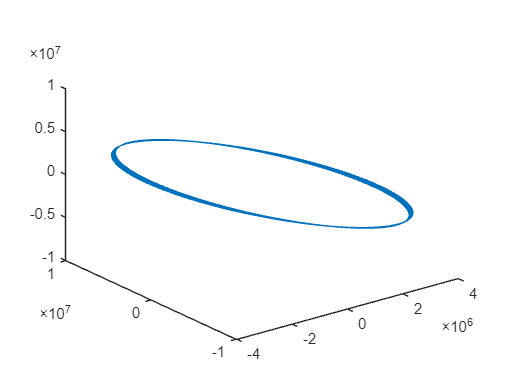

plot3(const_initialPosition(1,:),(const_initialPosition(2,:)),const_initialPosition(3,:))

% Ground stations
ac = access(const_Y,gs);
intvls = accessIntervals(ac)

intvls = 6×8 table
              Source                     Target          IntervalNumber         StartTime                EndTime           Duration    StartOrbit    EndOrbit
    ___________________________    __________________    ______________    ____________________    ____________________    ________    __________    ________

    "Constellation satellite 1"    "Ground station 1"          1           02-Jun-2020 14:38:00    02-Jun-2020 14:57:00      1140           4            4   
    "Constellation satellite 1"    "Ground station 1"          2           02-Jun-2020 16:39:00    02-Jun-2020 17:04:00      1500           5            5   
    "Constellation satellite 1"    "Ground station 1"          3           0

% Simulink model
a1 = const_semiMajorAxis;
a2 = const_semiMajorAxis-900000;
aTransfer = (a1+a2)/2;
e1 = const_eccentricity(const_n);
i1 = const_inclination(const_n);
raan1 = const_rightAscensionOfAscendingNode(const_n);
w1 = const_argumentOfPeriapsis(const_n);
theta1 = const_trueAnomaly(const_n);
mu = 398600.4418e9;

% Time of transfer
tTransfer = pi*sqrt((aTransfer^3)/mu)

tTransfer = 3.3427e+03


% Delta V Calculation
v1 = sqrt(mu/a1);
vTransfer1 = sqrt(2*mu*((1/a1) - (1/(2*aTransfer))));
const_deltav1 = vTransfer1 - v1

const_deltav1 = -208.6290


v2 = sqrt(mu/a2);
vTransfer2 = sqrt(2*mu*((1/a2) - (1/(2*aTransfer))));
const_deltav2 = v2 - vTransfer2

const_deltav2 = -214.8496


% Outward burn
thetaStar = 0;
const_deltav1Direction = [- cosd(raan1)*sind(w1 + thetaStar) - sind(raan1)*cosd(i1)*cosd(w1 + thetaStar); ...
    - sind(raan1)*sind(w1 + thetaStar) + cosd(raan1)*cosd(i1)*cosd(w1 + thetaStar); ...
    sind(i1)*cosd(w1 + thetaStar)];

% Recircularisation burn
thetaStar = 180;
const_deltav2Direction = [- cosd(raan1)*sind(w1 + thetaStar) - sind(raan1)*cosd(i1)*cosd(w1 + thetaStar); ...
    - sind(raan1)*sind(w1 + thetaStar) + cosd(raan1)*cosd(i1)*cosd(w1 + thetaStar); ...
    sind(i1)*cosd(w1 + thetaStar)];

% Calculating burns
g0 = 9.81;
Isp = 400;
ve = (g0*Isp);
mDot = 500;
m0 = 1000;

% Outward burn
m1 = m0/exp(-const_deltav1/ve)

m1 = 948.2212

const_burnDuration1 = (m0-m1)/mDot

const_burnDuration1 = 0.1036


% Recircularisation burn
m2 = m1/exp(-const_deltav2/ve);
const_burnDuration2 = (m1-m2)/mDot

const_burnDuration2 = 0.1010

% Calculating distance between satellites and debris
raan1 = const_rightAscensionOfAscendingNode(const_n);
w1 = const_argumentOfPeriapsis(const_n);
i1 = const_inclination(const_n);
thetaStar = 0;
thetaStar = 180;

[~,~,range,tOut] = aer(const_Y(),Y())

range = 1.0e+07 *

    1.0644    1.1139    1.1618    1.2076    1.2512    1.2922    1.3306    1.3660    1.3984    1.4275    1.4534    1.4758    1.4947    1.5100    1.5217    1.5297    1.5339    1.5344    1.5311    1.5241    1.5133    1.4989    1.4809    1.4593    1.4342    1.4058    1.3741    1.3393    1.3015    1.2609    1.2176    1.1720    1.1242    1.0745    1.0232    0.9707    0.9174    0.8638    0.8105    0.7581    0.7076    0.6599    0.6164    0.5784    0.5475    0.5255    0.5136    0.5128    0.5231    0.5436


tOut = 1×1441 datetime array
Columns 1 through 1424

   02-Jun-2020 08:23:00   02-Jun-2020 08:24:00   02-Jun-2020 08:25:00   02-Jun-2020 08:26:00   02-Jun-2020 08:27:00   02-Jun-2020 08:28:00   02-Jun-2020 08:29:00   02-Jun-2020 08:30:00   02-Jun-2020 08:31:00   02-Jun-2020 08:32:00   02-Jun-2020 08:33:00   02-Jun-2020 08:34:00   02-Jun-2020 08:35:00   02-Jun-2020 08:36:00   02-Jun-2020 08:37:00   02-Jun-2020 08:38:00   02-Jun-2020 08:39:00   02-Jun-2020 08:40:00   02-Jun-2020 08:41:00   02-Jun-2020 08:42:00   02-Jun-2020 08:43:00   02-Jun-2020 08:44:00   02-Jun-2020 08:45:00   02-Jun-2020 08:46:00   02-Jun-2020 08:47:00   02-Jun-2020 08:48:00   02-Jun-2020 08:49:00   02-Jun-2020 08:50:00   02-Jun-2020 08:51:00   02-Jun-2020 08:52:00   02-Jun-2020 08:53:00   02-Jun-2020 08:54:00   02-Jun-2020 08:55:00   02-Jun-2020 08:56:00   02-Jun-2020 08:57:00   02-Jun-2020 08:58:00   02-Jun-2020 08:59:00   02-Jun-2020 09:00:00   02-Jun-2020 09:01:00   02-Jun-2020 09:02:00   02-Jun-2020 09:03:00   0


% Create plot of tOut and range
h2 = plot(tOut,range,"DisplayName","range")

h2 =   Line (range) with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [02-Jun-2020 08:23:00    02-Jun-2020 08:24:00    02-Jun-2020 08:25:00    02-Jun-2020 08:26:00    02-Jun-2020 08:27:00    02-Jun-2020 08:28:00    02-Jun-2020 08:29:00    02-Jun-2020 08:30:00    …    ] (1×1441 datetime)
              YData: [1.0644e+07 1.1139e+07 1.1618e+07 1.2076e+07 1.2512e+07 1.2922e+07 1.3306e+07 1.3660e+07 1.3984e+07 1.4275e+07 1.4534e+07 1.4758e+07 1.4947e+07 1.5100e+07 1.5217e+07 1.5297e+07 1.5339e+07 1.5344e+07 1.5311e+07 … ] (1×1441 double)

  Show all properties

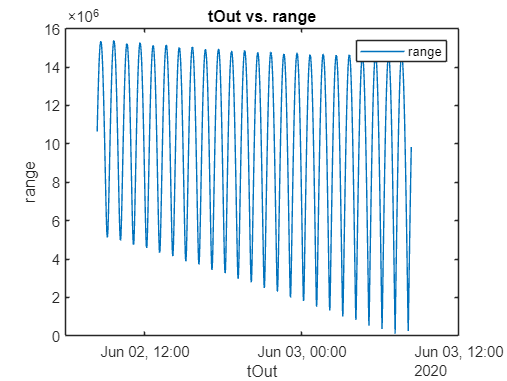


% Add xlabel, ylabel, title, and legend
xlabel("tOut")
ylabel("range")
title("tOut vs. range")
legend

% Collision windows
dMinTarget = 9000e3;           
kCloseIdx  = find(range<dMinTarget);
dW         = [0 diff(kCloseIdx)];
kWindow    = zeros(2,length(kCloseIdx));
j          = 1;
for m = 1:length(dW)
  if dW(m)~=1
    % single point window
    kWindow(1,j) = max(1,kCloseIdx(m)-1);
    kWindow(2,j) = kCloseIdx(m)+1;
    j = j+1;
  elseif j>1
    % update window end as long as diff==1
    kWindow(2,j-1) = kCloseIdx(m)+1;
  end
end

kWindow = kWindow(:,1:j-1);
fprintf("%d windows found for dMin = %g km\n",size(kWindow,2),dMinTarget*1e-3);

24 windows found for dMin = 9000 km




windows = tOut(kWindow)

windows = 2×24 datetime array
   02-Jun-2020 08:59:00   02-Jun-2020 09:59:00   02-Jun-2020 10:58:00   02-Jun-2020 11:58:00   02-Jun-2020 12:58:00   02-Jun-2020 13:58:00   02-Jun-2020 14:58:00   02-Jun-2020 15:58:00   02-Jun-2020 16:57:00   02-Jun-2020 17:57:00   02-Jun-2020 18:57:00   02-Jun-2020 19:57:00   02-Jun-2020 20:57:00   02-Jun-2020 21:57:00   02-Jun-2020 22:56:00   02-Jun-2020 23:56:00   03-Jun-2020 00:56:00   03-Jun-2020 01:56:00   03-Jun-2020 02:56:00   03-Jun-2020 03:56:00   03-Jun-2020 04:56:00   03-Jun-2020 05:56:00   03-Jun-2020 06:56:00   03-Jun-2020 07:56:00
   02-Jun-2020 09:20:00   02-Jun-2020 10:21:00   02-Jun-2020 11:21:00   02-Jun-2020 12:21:00   02-Jun-2020 13:21:00   02-Jun-2020 14:21:00   02-Jun-2020 15:21:00   02-Jun-2020 16:22:00   02-Jun-2020 17:21:00   02-Jun-2020 18:22:00   02-Jun-2020 19:22:00   02-Jun-2020 20:22:00   02-Jun-2020 21:22:00   02-Jun-2020 22:22:00   02-Jun-2020 23:22:00   03-Jun-2020 00:22:00   03-Jun-2020 01:22:00   03-Jun-2020 02:22:00   

if size(windows,2)>=3
  disp(windows(:,1:3)')
else
  disp(windows')
end

   02-Jun-2020 08:59:00   02-Jun-2020 09:20:00
   02-Jun-2020 09:59:00   02-Jun-2020 10:21:00
   02-Jun-2020 10:58:00   02-Jun-2020 11:21:00



% Point of closest approach
window = windows(:,1);
tVec   = window(1):seconds(2):window(2);
dRDot  = zeros(size(tVec))

dRDot =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


dR     = zeros(size(tVec))

dR =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


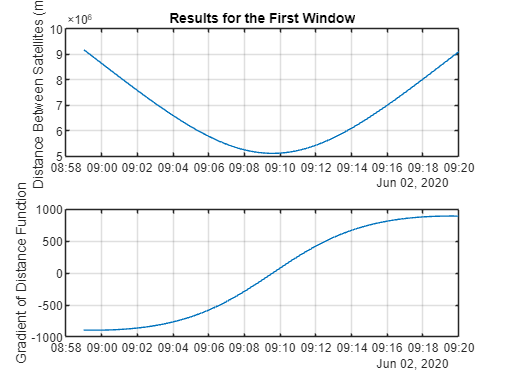

for k = 1:length(tVec)
  delT = days(tVec(k) - sc.StartTime);
  [dRDot(k),dR(k)] = gradientScenario(delT,const_Y,Y,startTime);
end

figure('name','Gradient Test over One Window')
subplot(211)
plot(tVec,dR)
grid on
ylabel('Distance Between Satellites (m)')
title('Results for the First Window')
subplot(212)
plot(tVec,dRDot)
grid on
ylabel('Gradient of Distance Function')

% Window of closest approach
tMin = zeros(1,size(windows,2));
dRs  = zeros(1,size(windows,2));
h = waitbar(0,'Please wait, iterating over windows...');
tic
for k = 1:size(windows,2)
  tMin(k) = fzero(@(t) gradientScenario(t,const_Y,Y,sc.StartTime),days(windows(:,k)-sc.StartTime));
  [~,dRs(k)] = gradientScenario(tMin(k),const_Y,Y,sc.StartTime);
  waitbar(k/size(windows,2),h)
end
close(h)
toc

Elapsed time is 2.417622 seconds.



% Minimum distance of all the windows and report the time of closest approach found
[rMin,iMin] = min(dRs);
tCA = sc.StartTime + tMin(iMin);
disp(tCA)

   03-Jun-2020 07:08:54




disp(dRs(iMin))

   9.2665e+04



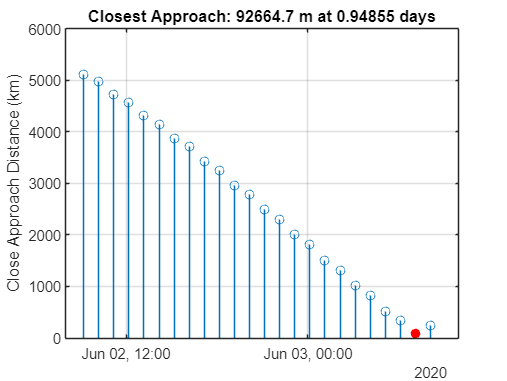


% Plot the resulting close passes
figure('name','ConjunctionDetection')
stem(sc.StartTime + tMin,dRs*1e-3)
ylabel('Close Approach Distance (km)')
title(sprintf('Closest Approach: %g m at %g days',rMin,tMin(iMin)))
hold on; grid on;
stem(sc.StartTime + tMin(iMin),rMin*1e-3,'filled','r') % mark the closest approach

% Running simulink model
o = datevec(tCA)

o = 1.0e+03 *

    2.0200    0.0060    0.0030    0.0070    0.0080    0.0548


p = datevec(startTime)

p =         2020           6           2           8          23           0


a = etime(o,p)

a = 8.1955e+04

const_t1 = a;
const_t2 = const_t1 + tTransfer

const_t2 = 8.5297e+04


open_system("C:\Users\prath\Desktop\ACODS\Prathap\matlab code\sim_v2.slx");
simOut = sim("C:\Users\prath\Desktop\ACODS\Prathap\matlab code\sim_v2.slx");

positionTT = timeseries2timetable(simOut.yout{1}.Values)

positionTT = 51×1 timetable
     Time                        Data                  
    _______    ________________________________________

    0 sec      6.6909e+05     5.2261e+06    -6.1821e+06
    0.2 sec    6.6847e+05     5.2271e+06    -6.1813e+06
    0.4 sec    6.6785e+05     5.2281e+06    -6.1805e+06
    0.6 sec    6.6724e+05     5.2291e+06    -6.1797e+06
    0.8 sec    6.6662e+05     5.2301e+06     -6.179e+06
    1 sec        6.66e+05     5.2311e+06    -6.1782e+06
    1.2 sec    6.6538e+05     5.2321e+06    -6.1774e+06
    1.4 sec    6.6477e+05     5.2331e+06    -6.1767e+06
    1.6 sec    6.6415e+05     5.2341e+06    -6.1759e+06
    1.8 sec    6.6353e+05     5.2351e+06    -6.1751e+06
    2 sec      6.6291e+05      5.236e+06    

attitudeTT = timeseries2timetable(simOut.yout{2}.Values)

attitudeTT = 51×1 timetable
     Time        Data   
    _______    _________

    0 sec      2.459e+06
    0.2 sec    2.459e+06
    0.4 sec    2.459e+06
    0.6 sec    2.459e+06
    0.8 sec    2.459e+06
    1 sec      2.459e+06
    1.2 sec    2.459e+06
    1.4 sec    2.459e+06
    1.6 sec    2.459e+06
    1.8 sec    2.459e+06
    2 sec      2.459e+06
    2.2 sec    2.459e+06
    2.4 sec    2.459e+06
    2.6 sec    2.459e+06
    2.8 sec    2.459e+06
    3 sec      2.459e+06


sat = satellite(sc,positionTT,Name = "1");
v = satelliteScenarioViewer(sc,CameraReferenceFrame = "Inertial");

play(sc,PlaybackSpeedMultiplier=40)